x = linspace(0,1,100);
t = linspace(0,1,100);
m = 0;
sol = pdepe(m,@pdex1pde,@pdex1ic,@pdex1bc,x,t);
u = sol(:,:,1)

u =          0    0.0317    0.0634    0.0951    0.1266    0.1580    0.1893    0.2203    0.2511    0.2817    0.3120    0.3420    0.3717    0.4009    0.4298    0.4582    0.4862    0.5137    0.5406    0.5671    0.5929    0.6182    0.6428    0.6668    0.6901    0.7127    0.7346    0.7557    0.7761    0.7958    0.8146    0.8326    0.8497    0.8660    0.8815    0.8960    0.9096    0.9224    0.9341    0.9450    0.9549    0.9638    0.9718    0.9788    0.9848    0.9898    0.9938    0.9969    0.9989    0.9999
         0    0.0298    0.0595    0.0890    0.1184    0.1476    0.1766    0.2053    0.2337    0.2619    0.2898    0.3173    0.3445    0.3713    0.3977    0.4237    0.4492    0.4742    0.4988    0.5229    0.5464    0.5694    0.5918    0.6135    0.6347    0.6553    0.6751    0.6943    0.7128    0.7306    0.7477    0.7640    0.7796    0.7944    0.8083    0.8215    0.8339    0.8454    0.8561    0.8659    0.8749    0.8830    0.8902    0.8966    0.9020    0.9065    0.9102    0.9129    0.9147    0

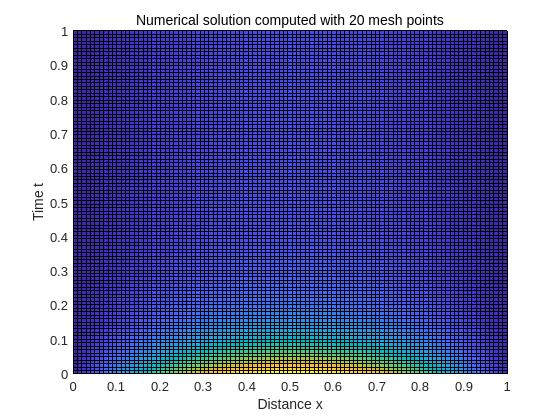

surf(x,t,u)
title('Numerical solution computed with 20 mesh points')
xlabel('Distance x')
ylabel('Time t')

view([-0.600 90.000])
grid off

function [c,f,s] = pdex1pde(x,t,u,dudx) % Equation to solve
c = 1;
f = dudx;
s = 1;
end
%----------------------------------------------
function u0 = pdex1ic(x) % Initial conditions
u0 = sin(pi*x);
end
%----------------------------------------------
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t) % Boundary conditions
pl = ul;
ql = 0;
pr = ur;
qr = 0;
end
%----------------------------------------------
